% % % MANIPULATOR % % %
clear; clc;

% --- USING DH PARAMETER
% --- joint angle (x_i to xi over z_i)
theta0 = deg2rad(0);
theta1 = deg2rad(0); % var
theta2 = deg2rad(0); % var
theta3 = deg2rad(0);
% --- joint offset (O_i to xi over z_i)
d0 = 0.100;
d1 = 0.180;
d2 = 0.100;
d3 = -0.250; % var
% --- link lengths (Oi to z_i over xi)
a0 = 0.0;
a1 = 0.300; 
a2 = 0.300;
a3 = 0.0;
% --- link twist (z_i to zi over xi)
alpha0 = deg2rad(90);
alpha1 = deg2rad(0);
alpha2 = deg2rad(0);
alpha3 = deg2rad(128);

% --- [a    alpha            d    theta]
dhparams = [
    [a0   alpha0  d0  theta0]; 
    [a1   alpha1  d1  theta1];
    [a2   alpha2  d2  theta2];
    [a3   alpha3  d3  theta3]
    ];


% --- USING HOMOGENEOUS TRANSFORMATION MATRIX
% --- homogeneous transformation matrix
T01 = [
    [  0.    0.    1.    0.     ];
    [ -1.    0.    0.    0.     ];
    [  0.   -1.    0.    0.100  ];
    [  0.    0.    0.    1.     ]
    ];
T12 = [
    [  0.25881905   0.  -0.96592583   0.180  ];
    [  0.           1.   0.           0.     ];
    [  0.96592583   0.   0.25881905   0.240  ];
    [  0.           0.   0.           1.     ]
    ];
T23 = [
    [ -0.61566148   0.   0.78801075   0.300  ];
    [  0.           1.   0.           0.     ];
    [ -0.78801075   0.  -0.61566148   0.     ];
    [  0.           0.   0.           1.     ]
    ];
T34 = [
    [  1.    0.    0.    0.     ];
    [  0.    1.    0.    0.     ];
    [  0.    0.    1.   -0.200  ];
    [  0.    0.    0.    1.     ]
    ];



% --- create robot object of rigidBodyTree
robot = rigidBodyTree;

% --- create link and joint object 
link1 = rigidBody('link1');
joint1 = rigidBodyJoint ('joint1', 'revolute');
joint1.PositionLimits = [-pi, 0];

link2 = rigidBody('link2');
joint2 = rigidBodyJoint('joint2', 'revolute');
joint2.PositionLimits = [0, pi];

link3 = rigidBody('link3');
joint3 = rigidBodyJoint('joint3', 'fixed');

link4 = rigidBody('link4');
joint4 = rigidBodyJoint('joint4', 'prismatic');
joint4.PositionLimits = [-0.2, 0];

% --- specify the body-to-body transformation using DH parameters
% --- each fixed transform is relative to the previous joint coordinate frame 
% setFixedTransform(joint1, dhparams(1,:), 'dh');
% setFixedTransform(joint2, dhparams(2,:), 'dh');
% setFixedTransform(joint3, dhparams(3,:), 'dh');
% setFixedTransform(joint4, dhparams(4,:), 'dh');
setFixedTransform(joint1, T01);
setFixedTransform(joint2, T12);
setFixedTransform(joint3, T23);
setFixedTransform(joint4, T34);

link1.Joint = joint1;
link2.Joint = joint2;
link3.Joint = joint3;
link4.Joint = joint4;

% --- attach the first body joint to the base frame
% --- specify the previous body name when calling addBody to attach it 
% --- addBody(robot_object, body, parent_name) 
addBody(robot, link1, 'base');
addBody(robot, link2, 'link1');
addBody(robot, link3, 'link2');
addBody(robot, link4, 'link3');

showdetails(robot);

--------------------
Robot: (4 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   link3(3)  
   3        link3        joint3         fixed            link2(2)   link4(4)  
   4        link4        joint4     prismatic            link3(3)   
--------------------


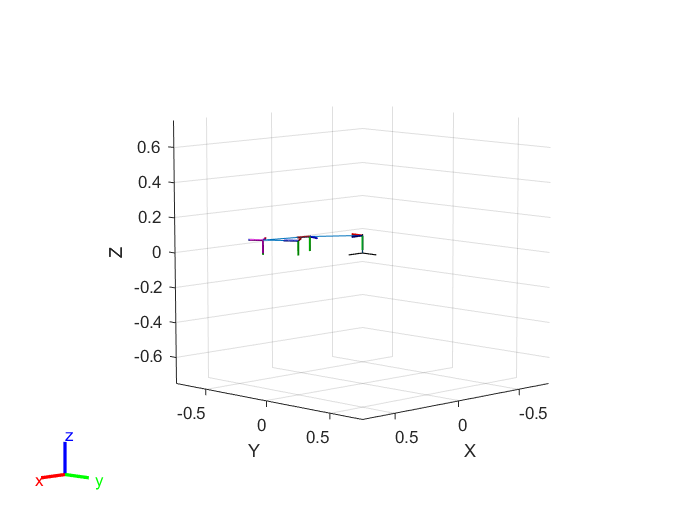

% --- plot the robot
show(robot);
axis([-0.75,0.75,-0.75,0.75,-0.75,0.75]);

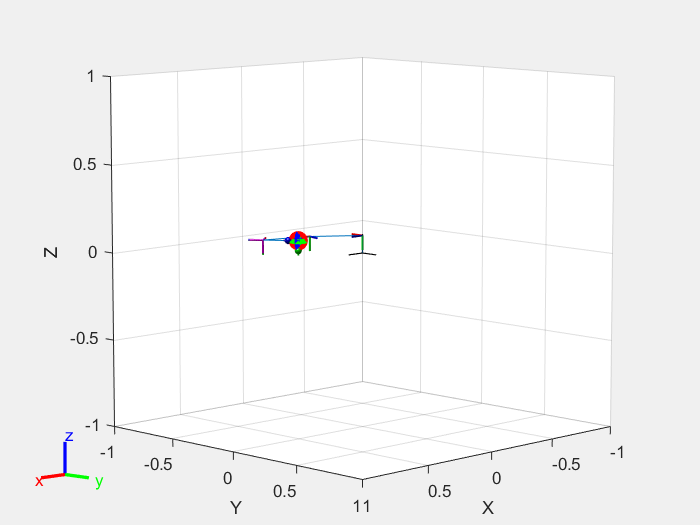

gui = interactiveRigidBodyTree(robot, MarkerScaleFactor=0.2);

openExample('robotics/BuildAManipulatorRobotUsingDenavitHartenbergParametersExample')